# ICO7

# Amelia Rotondo 

# CWID: 887925113

## Part 1: Autonomous Differential Equation 

#### dy/dx = sin(y)

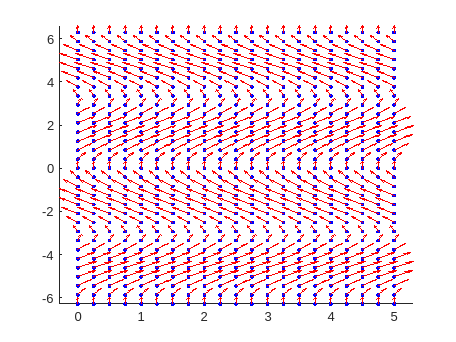

% Establish Autonomous DE
x=linspace(0,5,21); y=linspace(-2*pi, 2*pi, 31);
[X,Y]=meshgrid(x,y);
DX=sin(Y); DY=1+0*X;

% Develop Plot
figure(1); clf; hold on; axis tight;
plot(X,Y,'.b');
quiver(X, Y,DX,DY, 'r');

## Part 2: Solving the ODE 

#### Using ode45

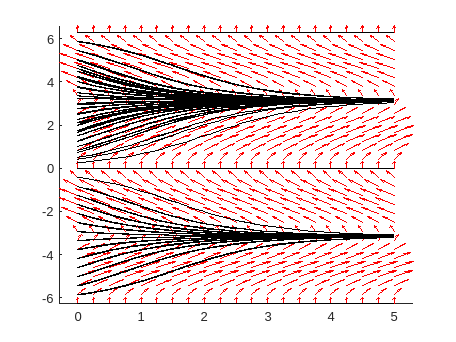

g = @(x,y) sin(y);
figure(2); clf; hold on; axis tight;
quiver(X, Y, DX, DY, 'r');
for i = 1:length(y)
    for j = 1:length(x)
        [xx, yy]=ode45(g, [0 5], [X(i,j) Y(i,j)]);
        plot(xx,yy,'k-');
    end
end